%% Graph Theory code
% Adjacency matrix
Adj=[ 0 1 1 1; 1 0 0 0 ; 1 0 0 1; 1 0 1 0];
% Degree matrix
Deg= [ 3 0 0 0; 0 1 0 0 ; 0 0 2 0; 0 0 0 2];
% Laplacian matrix= Degree-Adjacency 
Lap= Deg-Adj;

%% State space ystem
A= [-2 1 0; 1 -1 1; 0 -2 0];
B= [0 ; 0 ; 3];
C= [1 0 0];
I=[1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1];

%define unknown matrix which need to be determined by LMI
setlmis([])
[np,m]         =  size(B);
p              =  size(C,1);

% Specify the structure and size of LMI variables
P1   = lmivar(1,[np,1]);
L1   = lmivar(2,[m,np]);
W1   = lmivar(1,[1,0]*m);

%%%  Agent 1
%% First LMI
%first term A'P+PA
lmiterm ([1 1 1 P1],1,A, 's');   
%second term PB
lmiterm ([1 1 2 P1],1, B) ;    
%third term B'P
lmiterm ([1 2 1 P1],B',1) ; 
%fourth term -2W
lmiterm ([1 2 2 W1],-2 ,1);  
%% Second LMI
lmiterm([2,1,1,P1],-1,1);
%finishing description
LMISYS1 = getlmis;
%% check the feasibility
[tmin,xfeas] = feasp(LMISYS1);


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        0.211287
     2                        0.047194
     3                        0.027643
     4                       -0.050313

 Result:  best value of t:    -0.050313
          f-radius saturation:  0.000% of R =  1.00e+09
 


%LMI Solution
P1opt=dec2mat (LMISYS1, xfeas, P1);
L1opt=dec2mat(LMISYS1, xfeas, L1);
W1opt=dec2mat(LMISYS1, xfeas, W1);
K1=L1opt*inv(W1opt)

K1 =      0     0     0


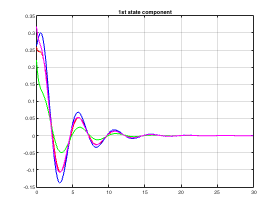


%% MAS CL system dynamics
Anew= (kron(I,A));
Bnew=(kron(I,B));
K1new=(kron(Lap,K1));
D=0;
sys1=ss(Anew,Bnew,K1new,D);

% Agent initial position (random)
x0=rand(12,1);

t = 0:0.01:30;
u=zeros(size(t,2),size(Bnew,2)); 
                                   
[y1,t,x1]=lsim(sys1, u, t, x0);

%% Plot
% first state component of all agents 
figure;
plot(t,x1(:,1),'r');   
hold on
plot(t,x1(:,4),'b');   
plot(t,x1(:,7),'g');   
plot(t,x1(:,10),'m'); 
grid on
title('1st state component')
hold off

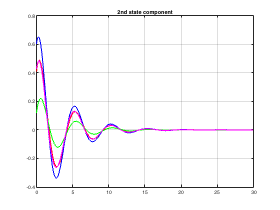

% second state component of all agents 
figure;
plot(t,x1(:,2),'r');  
hold on
plot(t,x1(:,5),'b');
plot(t,x1(:,8),'g');
plot(t,x1(:,11),'m');
grid on
title('2nd state component')
hold off

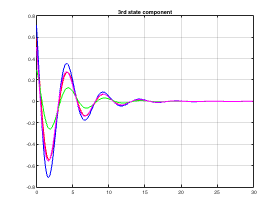

% third state component of all agents 
figure;
plot(t,x1(:,3),'r');
hold on
plot(t,x1(:,6),'b');
plot(t,x1(:,9),'g');
plot(t,x1(:,12),'m');
grid on
title('3rd state component')
hold off